## 1)

We create a one layered neural network and observe a plane of output values a two feature input

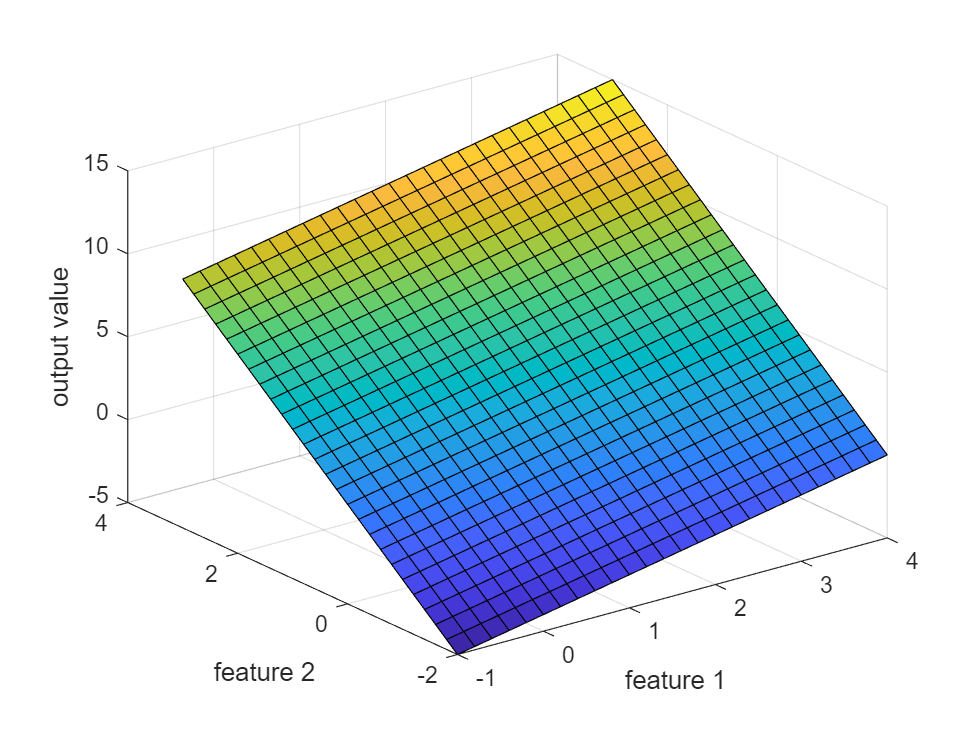

clear
w=[3;1];
x1=[-1:.2:4];
x2=[-2:.2:3];
x3=[x1;x2];
b=1;
for i=1:length(x1)
for k=1:length(x2)
x(:,b)=[x3(1,i);x3(2,k)];
y(i,k)=w'*x(:,b);
b=b+1;
end
end
figure(1)
surf(x1,x2,y);
xlabel('feature 1')
ylabel('feature 2')
zlabel('output value')

## Different weights

Modification of the weight vector resulted in a steeper plane

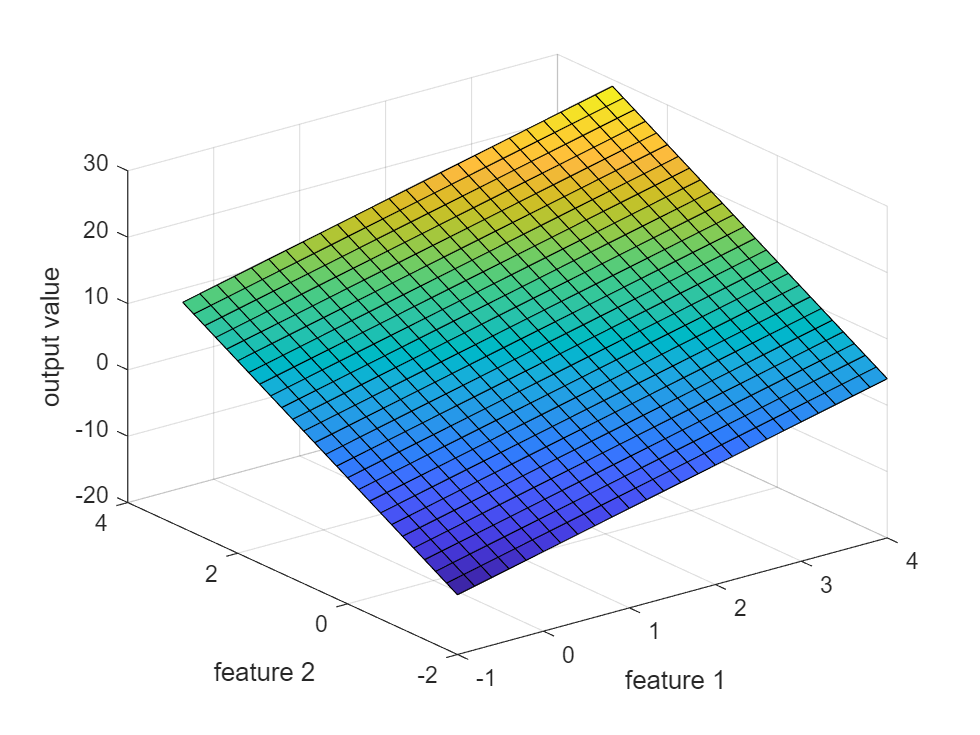

w=[5;3];
x1=[-1:.2:4];
x2=[-2:.2:3];
x3=[x1;x2];
b=1;
for i=1:length(x1)
for k=1:length(x2)
x(:,b)=[x3(1,i);x3(2,k)];
y(i,k)=w'*x(:,b);
b=b+1;
end
end
figure(2)
surf(x1,x2,y);
xlabel('feature 1')
ylabel('feature 2')
zlabel('output value')

## 2)

Normalisation of the input matrix results in a curved output plane spaning a considerably smaller range

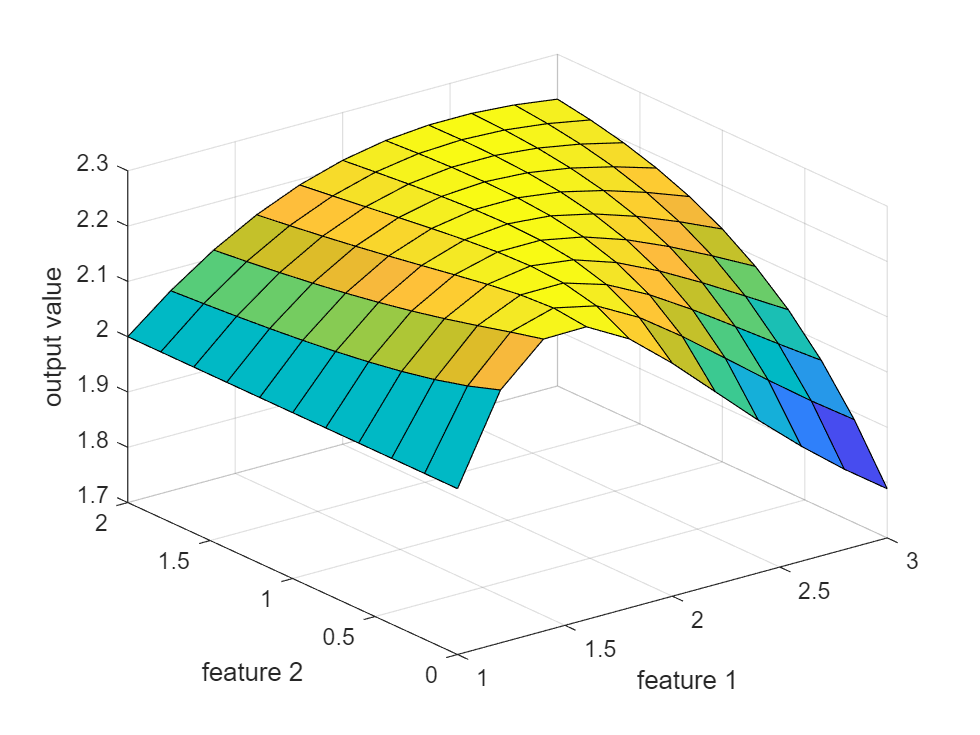

clear
w=[2;1];
x1=[1:.2:3];
x2=[0:.2:2];
x3=[x1;x2];
b=1;
for i=1:length(x1)
for k=1:length(x2)
x(:,b)=[x3(1,i);x3(2,k)];
y(i,k)=w'*normc(x(:,b));
b=b+1;
end
end
figure(3)
surf(x1,x2,y);
xlabel('feature 1')
ylabel('feature 2')
zlabel('output value')

## norm w and x

normalisation of both input and weight vectors forms a similar curvature and spaning yet smaller value range

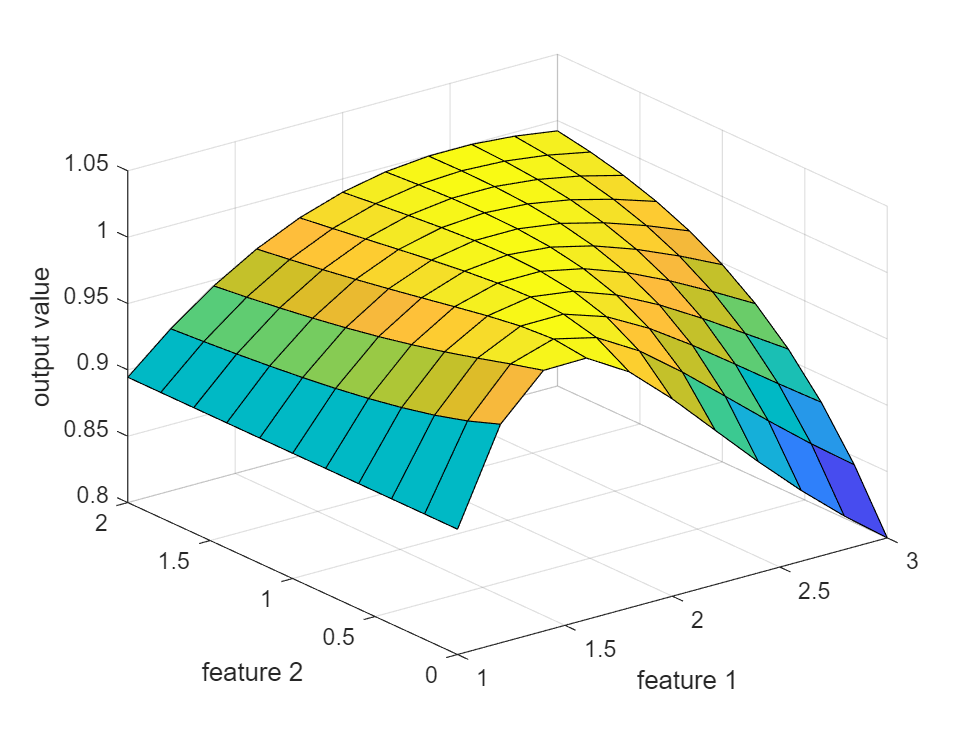

clear
w=[2;1];
x1=[1:.2:3];
x2=[0:.2:2];
x3=[x1;x2];
b=1;
normw=normc(w);
for i=1:length(x1)
for k=1:length(x2)
x(:,b)=[x3(1,i);x3(2,k)];
y(i,k)=normw'*normc(x(:,b));
b=b+1;
end
end
figure(4)
surf(x1,x2,y);
xlabel('feature 1')
ylabel('feature 2')
zlabel('output value')

## 4) 

Here in yellow are presented potential solutions for a neuron constricted using function hardlim

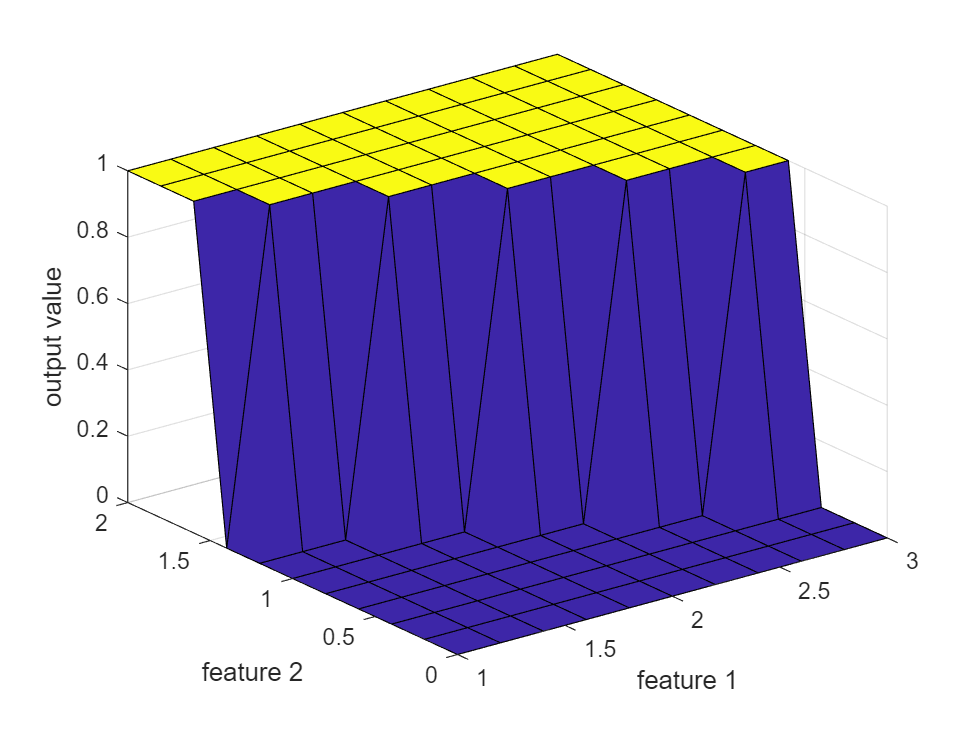

w=[2;1];
x1=[1:.2:3];
x2=[0:.2:2];
x3=[x1;x2];
b=1;
threshold=5;
for i=1:length(x1)
for k=1:length(x2)
x(:,b)=[x3(1,i);x3(2,k)];
y(i,k)=hardlim(w'*x(:,b)-threshold);
b=b+1;
end
end
figure(5)
surf(x1,x2,y)
xlabel('feature 1')
ylabel('feature 2')
zlabel('output value')

## 5)

applying hardlim alongside mormalisation results in clear representation of best solutions

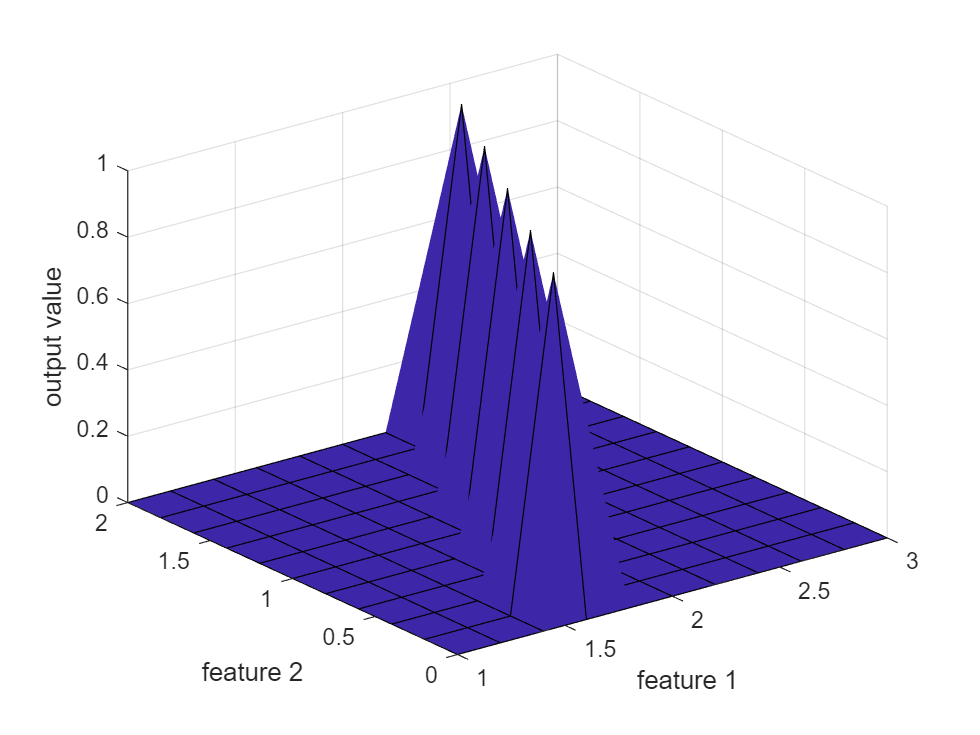

w=[2;1];
x1=[1:.2:3];
x2=[0:.2:2];
x3=[x1;x2];
b=1;
threshold=0.9999;
normw=normc(w);
for i=1:length(x1)
for k=1:length(x2)
x=normc([x1(i);x2(k)]);
y(i,k)=hardlim(normw'*x-threshold);
b=b+1;
end
end
figure(6)
surf(x1,x2,y)
xlabel('feature 1')
ylabel('feature 2')
zlabel('output value')

## 6)

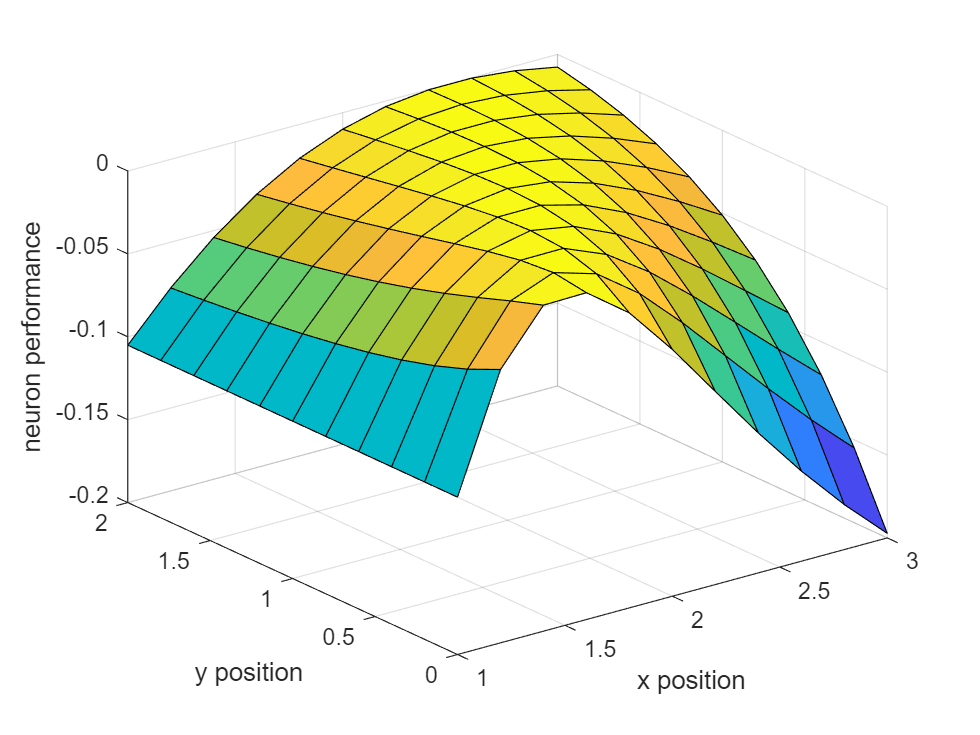

clear
w=[2;1];
x1=[1:.2:3];
x2=[0:.2:2];
x3=[x1;x2];
b=1;
bias=0.9999;
normw=normc(w);
for i=1:length(x1)
for k=1:length(x2)
x=normc([x1(i);x2(k)]);
y(i,k)=tansig(normw'*x-bias);
b=b+1;
end
end
figure(6)
surf(x1,x2,y)
hold on
xlabel('x position')
ylabel('y position')
zlabel('neuron performance')

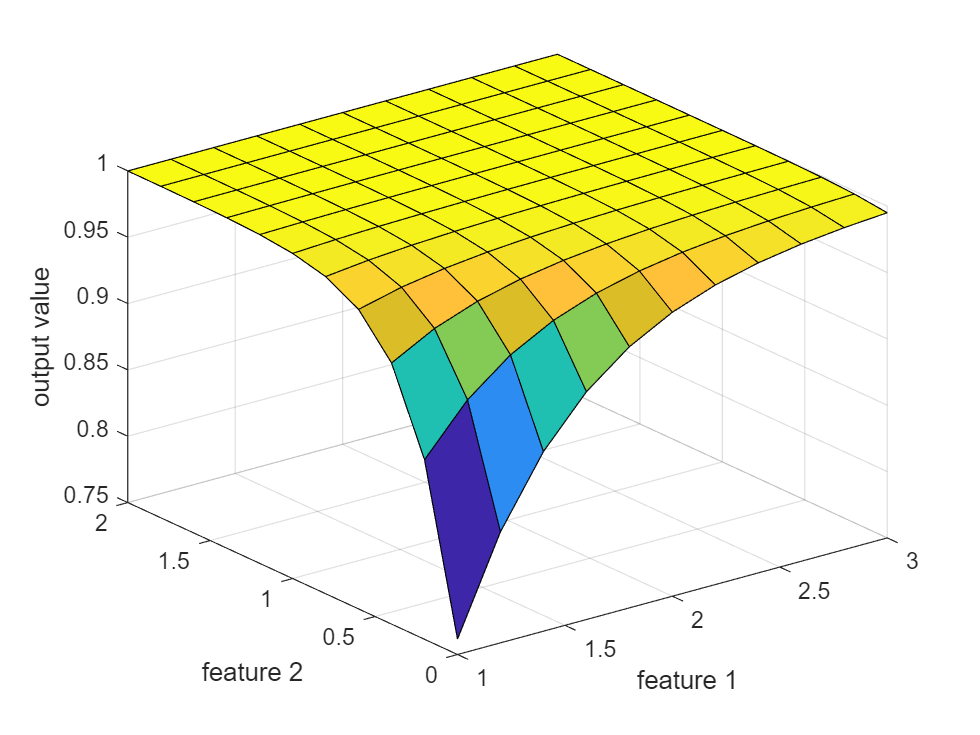


for i=1:length(x1)
for k=1:length(x2)
x(:,b)=[x3(1,i);x3(2,k)];
y(i,k)=tansig(w'*x(:,b)-bias);
b=b+1;
end
end
figure(7)
surf(x1,x2,y)
xlabel('feature 1')
ylabel('feature 2')
zlabel('output value')

In this task we will be creating a one layer network which will be used for evaluation of

different animal types based on 5 features:

1. How many legs

2. Does it live In a water

3. Does it fly

4. Has it blades

5. I sit an egg generative.

We will start by testing the network by identifying a mammal, a bird and a fish, then we will

also look at the results of normalization of the features.

clear

w=[4,2,1;0.01,-1,3.5;0.01,2,0.01;-1,2.5,-2;-1.5,2,1.5];
fox=[4;-1;-1;-0.9;-1];
salmon=[-1;4;-1;-2;1];
chicken =[2;-1;0.01;3;3];
cat=[4;0;0;-0.5;-2];
x=[ fox, salmon, chicken, cat];
y=w'*x;

5 features and four animals

% disp('x');
disp(x);

    4.0000   -1.0000    2.0000    4.0000
   -1.0000    4.0000   -1.0000         0
   -1.0000   -1.0000    0.0100         0
   -0.9000   -2.0000    3.0000   -0.5000
   -1.0000    1.0000    3.0000   -2.0000



Networks prediction of animal type,

We see it is overly confident in every but one example 

% disp('y');
disp(y);

   18.3800   -3.4700    0.4901   19.5000
    2.7500  -11.0000   18.5200    2.7500
    0.7900   18.4900   -2.9999    2.0000



we use normalization to limit output values and medigate over confidense

y=w'*normc(x);
disp('y when normc(x)');

y when normc(x)


we get marginally better results

disp(y);

    4.1296   -0.7235    0.1022    4.3333
    0.6179   -2.2937    3.8617    0.6111
    0.1775    3.8554   -0.6255    0.4444




y=normc(w)'*x;
disp('y when normc(w)');

y when normc(w)


disp(y);

    4.1892   -0.7909    0.1117    4.4444
    0.6268   -2.5071    4.2211    0.6268
    0.1789    4.1871   -0.6793    0.4529





y=normc(w)'*normc(x);
disp('y when normc(x) and normc(w)');

y when normc(x) and normc(w)


now all values are in -1 to 1 range

disp(y);

    0.9412   -0.1649    0.0233    0.9877
    0.1408   -0.5228    0.8802    0.1393
    0.0402    0.8731   -0.1417    0.1006



clear
w=[2;1];
x1=[-1:.2:4];
x2=[-2:.2:3];
z=[x1;x2];
a=1;
xu=[];
for i=1:length(x1)
for j=1:length(x2)
x(:,a)=[x1(i);x2(i)];
xu=[xu x(:,a)];
a=a+1;
end
end
y=w'*x;
t=w'*xu;

myNeuralNetworkFunction is generated using nnstart for fitting using x and y as training data

clear
x1=[1:0.1:3];
x2=[0:0.1:2];
n=1;
y=zeros(length(x1),length(x2));
for i=1:length(x2)
for j=1:length(x1)
x(:,n)=normc([x1(i);x2(j)]);
y(i,j)=myNeuralNetworkFunction(normc([x1(i);x2(j)]));
end
end

we see output values for a one layer neuron network range closley to 1

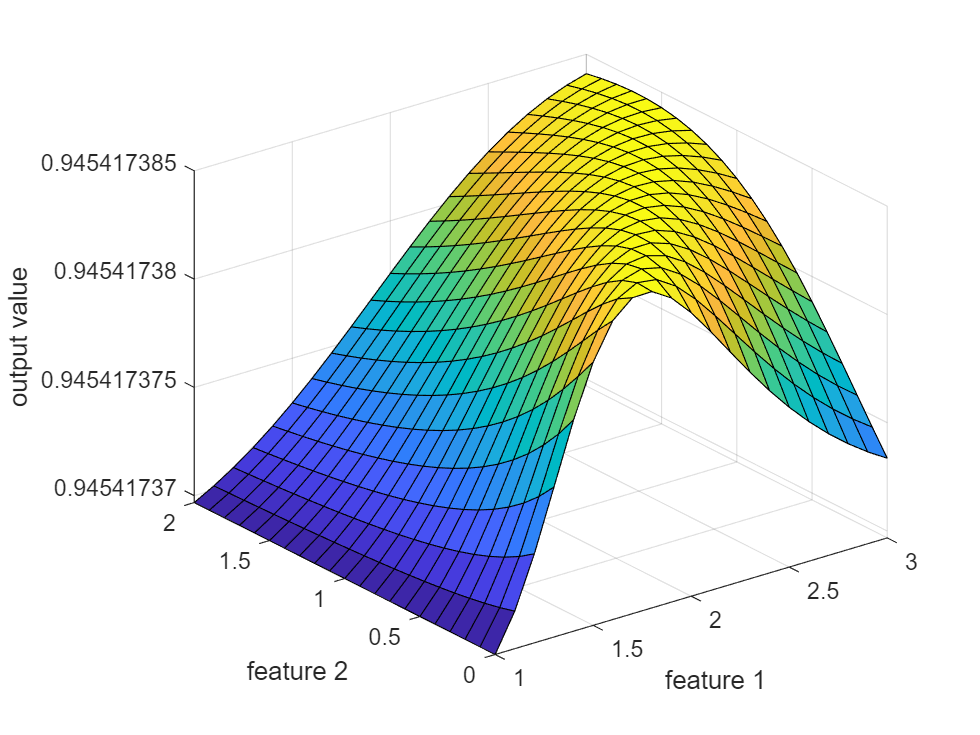

figure(8)
surf(x1,x2,y);
xlabel('feature 1')
ylabel('feature 2')
zlabel('output value')

Here we generate a set of random data following a line

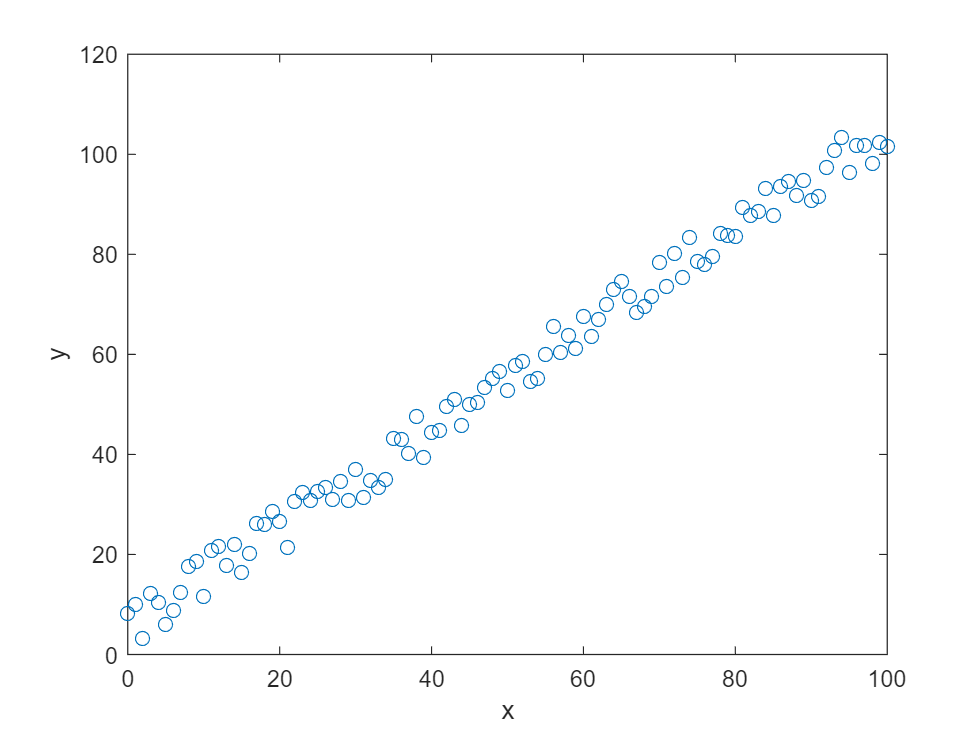

clear;
x=0:100;
z=10*rand(1,101);
y=x+z;
w=[2;1];
figure(9)
plot(x,y,'o');
xlabel('x')
ylabel('y')

a one layered NN trained on x given y

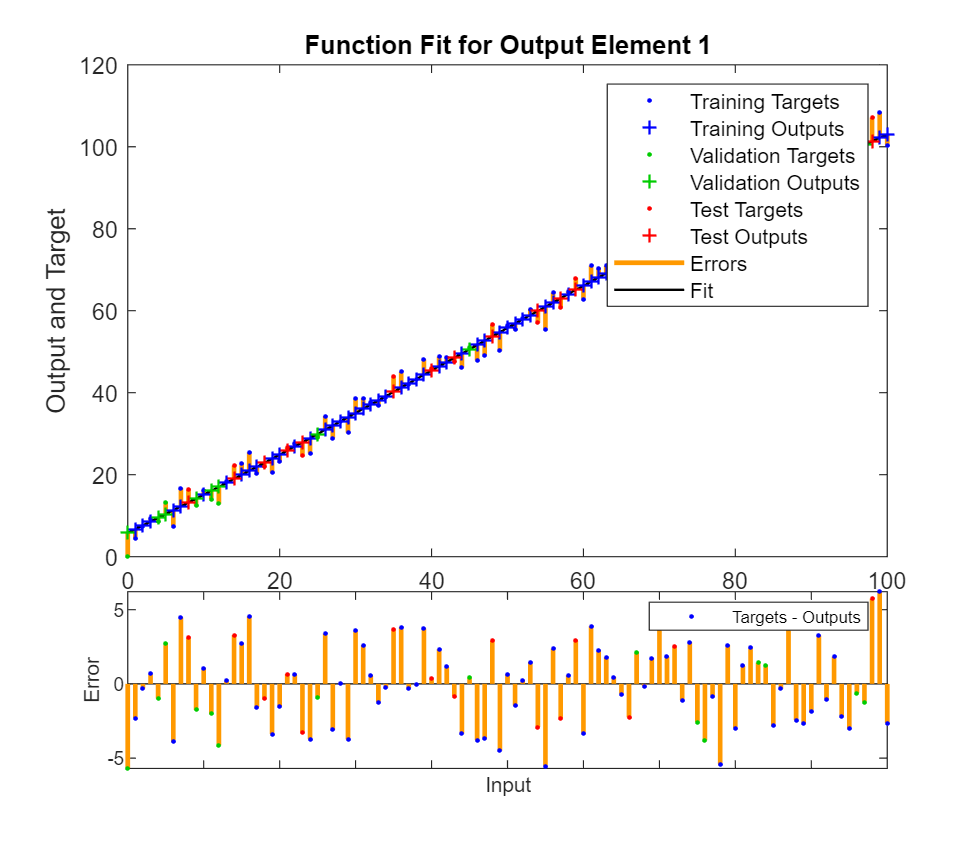

figure(10);
open untitled.fig;

conveging rate graphs for trainig, validation and testing set

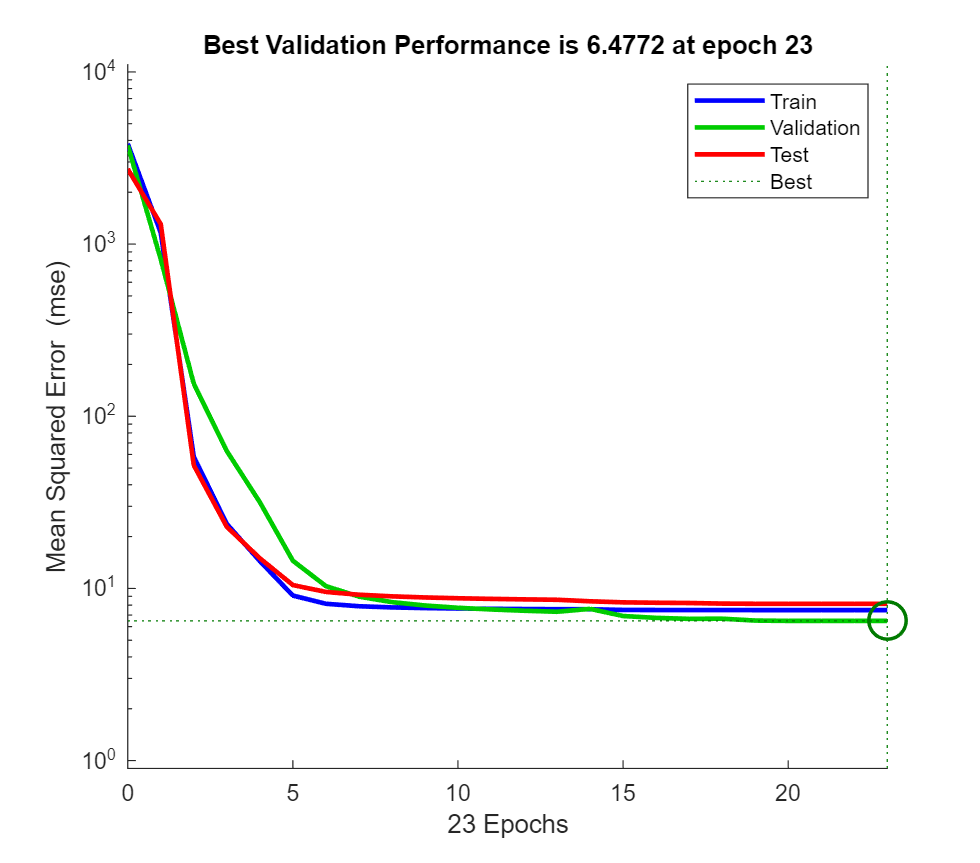

figure(11);
open untitled2.fig;